# Constraint Analysis Walkthrough — highest fidelity

This live script builds the F-16A constraint diagram with the **highest-fidelity** discipline models available. It is the companion to `constraint_analysis_L1_walkthrough.mlx`. The method is identical; only the discipline objects change.

The highest-fidelity stack is: `F16AeroL3` for aerodynamics, `F16GeomL3` for geometry, and `F16PropL2` for propulsion. There is no L3 propulsion tier by design, so the L3 rung pairs the L3 aero and geometry with the L2 engine model. Any thrust number here comes from `F16PropL2`.

Method reference: Raymer, *Aircraft Design: A Conceptual Approach*, 6th ed., ch. 5. The L3 drag build-up is Raymer Eq. 12.24, with the supersonic wave-drag term from Eqs. 12.44 and 12.45.

This walkthrough does the following steps:

- it builds the L3 aerodynamics and geometry models and the L2 propulsion model

- it shows how geometry feeds the drag polar at this fidelity

- it assembles the eight F-16A constraint conditions

- it plots each constraint curve and their envelope

- it reads off the optimum design point

The coupled sizing loop ties this diagram to the mission and the weights. That loop is a separate pass. It is not shown here.

## Make the sizing framework visible

This block adds the framework to the MATLAB path. If you already ran `tests/run_all_tests`, the path is set and this block does nothing.

if isempty(which("f16a_spec_path"))
    try
        here = fileparts(matlab.desktop.editor.getActiveFilename);
    catch
        here = pwd;
    end
    root = here;
    while ~isfolder(fullfile(root, "src")) || ~isfolder(fullfile(root, "examples", "F16A"))
        parent = fileparts(root);
        if strcmp(parent, root)
            error("Could not find the sizing/ root. Add its src/, examples/, and VnV/ folders to the path, or run this file from inside air_vehicle_design/sizing.");
        end
        root = parent;
    end
    addpath(genpath(fullfile(root, "src")));
    addpath(genpath(fullfile(root, "examples")));
    addpath(genpath(fullfile(root, "VnV")));
end

## Build the highest-fidelity discipline models

The build order matters, because the objects depend on each other. First build the propulsion object. Then inject it into the geometry object, because the engine thrust sizes the nacelle diameter, and the nacelle sets the duct wetted area. Then inject the geometry object into the aerodynamics object, because the L3 drag build-up reads the real planform and the wetted areas live from geometry.

This dependency chain is the key difference from L1. At L1 the aero object carried the wing shape as spec scalars. At L3 the aero object reads geometry live, so a change in geometry moves the drag polar and therefore moves every constraint curve.

prop = F16PropL2(f16a_spec_path(2));
geom = F16GeomL3(f16a_spec_path(3), prop);
aero = F16AeroL3(geom, f16a_spec_path(3));

## What the models produce

The analysis builds its own atmosphere state for each condition. Here we build one example state, cruise at 36,000 ft and Mach 0.87, only to show what the models return at a single point.

state = AircraftState(36000, 0.87);
state

state =   AircraftState with properties:

    altitude_ft: 36000
           mach: 0.8700
          T_atm: 390.2882
          P_atm: 474.7109
            rho: 7.0857e-04
              a: 968.4707
              V: 842.5695
              q: 251.5161
          theta: 0.7525
          delta: 0.2243
        theta_0: 0.8664
        delta_0: 0.3674


The aerodynamics object returns the drag polar $ C_D = C_{D0} + K_1 C_L^2 + K_2 C_L $. At L3 the clean `CD0` is a component build-up over the wing, tails, fuselage, and duct. The clean `CLmax` is geometry-based, so it is lower than the L1 table value. The last row shows the polar at Mach 1.6, where a supersonic wave-drag term is added.

polar    = aero.drag_polar(state);
polarSup = aero.drag_polar(AircraftState(36000, 1.6));
aeroValues = [polar.CD0; polar.K1; polar.K2; aero.get_CLmax(state); aero.get_e_osw(); ...
    aero.get_CLmax_TO(); aero.get_CLmax_L(); aero.get_Delta_CD0_TO(state); aero.get_Delta_CD0_L(state); polarSup.CD0];
aeroSummary = table(aeroValues, 'VariableNames', "Value", 'RowNames', ...
    {'CD0  clean build-up (M0.87)', 'K1  induced-drag factor', 'K2  camber term', ...
     'CLmax  clean (geometry-based)', 'e  Oswald efficiency', 'CLmax  takeoff', 'CLmax  landing', ...
     'dCD0  takeoff', 'dCD0  landing', 'CD0  build-up + wave (M1.6)'})

aeroSummary = 10×1 table
                                       Value   
                                     __________

    CD0  clean build-up (M0.87)        0.016169
    K1  induced-drag factor             0.11677
    K2  camber term                  -0.0068493
    CLmax  clean (geometry-based)       0.91406
    e  Oswald efficiency                0.90862
    CLmax  takeoff                       1.2677
    CLmax  landing                       1.3856
    dCD0  takeoff                      0.048604
    dCD0  landing                      0.048604
    CD0  build-up + wave (M1.6)        0.038816


The propulsion object returns the afterburner and mil thrust, the thrust lapse $ \alpha = T/T_{SL} $ at both power settings, and the fuel consumption. The lapse comes from the Mattingly analytical model, not the L1 density law.

propValues = [prop.T_SL; prop.T_SL_mil; prop.thrust_lapse(state, "AB"); prop.compute_thrust_lapse_mil(state); ...
    prop.get_TSFC(state); prop.compute_TSFC_AB(state); prop.TR];
propSummary = table(propValues, 'VariableNames', "Value", 'RowNames', ...
    {'T_SL  AB sea-level thrust [lbf]', 'T_SL_mil  mil sea-level thrust [lbf]', ...
     'alpha  AB lapse (36 kft/M0.87)', 'alpha  mil lapse', ...
     'TSFC  mil [1/hr]', 'TSFC  AB [1/hr]', 'TR  throttle ratio'})

propSummary = 7×1 table
                                             Value 
                                            _______

    T_SL  AB sea-level thrust [lbf]           23770
    T_SL_mil  mil sea-level thrust [lbf]      15000
    alpha  AB lapse (36 kft/M0.87)           0.3674
    alpha  mil lapse                        0.22044
    TSFC  mil [1/hr]                         1.0071
    TSFC  AB [1/hr]                          1.5917
    TR  throttle ratio                            1


The geometry object returns the real planform and the wetted areas. The aero object reads these live, so they set the L3 drag build-up. The nacelle diameter and the duct area come from the injected engine thrust.

geomValues = [geom.S_ref; geom.b_wing; geom.cbar_wing; geom.get_S_wet(); geom.Amax; geom.L_aircraft];
geomSummary = table(geomValues, 'VariableNames', "Value", 'RowNames', ...
    {'S_ref  wing reference area [ft^2]', 'b_wing  span [ft]', 'MAC  mean aero chord [ft]', ...
     'S_wet  total wetted area [ft^2]', 'Amax  max cross-section [ft^2]', 'L_aircraft  overall length [ft]'})

geomSummary = 6×1 table
                                         Value 
                                         ______

    S_ref  wing reference area [ft^2]       300
    b_wing  span [ft]                        30
    MAC  mean aero chord [ft]             11.32
    S_wet  total wetted area [ft^2]      1488.3
    Amax  max cross-section [ft^2]       24.704
    L_aircraft  overall length [ft]       47.65


The next table maps each model output to the place where it enters the diagram.

## Assemble the constraint analysis

`ConstraintAnalysis.from_requirements` reads the eight F-16A conditions from `f16a_requirements.json` and injects the aero and prop objects into every condition. The call is identical to the L1 script; only the objects differ.

ca = ConstraintAnalysis.from_requirements(aero, prop, f16a_requirements_path(), ...
    F16ConstraintSet.constraint_map(), PointPerformanceBase.WS_RANGE_BRANDT);
nC = numel(ca.constraints);
condName = strings(nC,1); condClass = strings(nC,1); condRole = strings(nC,1);
for i = 1:nC
    c = ca.constraints{i};
    condName(i)  = c.name;
    condClass(i) = string(class(c));
    if isa(c, 'Only_WbyS'), condRole(i) = "W/S wall"; else, condRole(i) = "T/W producer"; end
end
conditions = table(condName, condClass, condRole, 'VariableNames', ["Condition", "ConstraintClass", "Role"])

conditions = 8×3 table
             Condition                   ConstraintClass              Role     
    ____________________________    _________________________    ______________

    "Max Mach"                      "LevelFlightConstraint"      "T/W producer"
    "Cruise"                        "LevelFlightConstraint"      "T/W producer"
    "Max Alt"                       "LevelFlightConstraint"      "T/W producer"
    "Combat Turn 1 (subsonic)"      "SustainedTurnConstraint"    "T/W producer"
    "Combat Turn 2 (supersonic)"    "SustainedTurnConstraint"    "T/W producer"
    "Excess Power"                  "ExcessPowerConstraint"      "T/W producer"
    "Takeoff"                       "TakeoffConstraint"          "T/W producer"
    "Landing"                       "LandingConstraint"          "W/S wall"    


## Individual constraint curves and their envelope

Each producer condition demands a minimum `T/W` at every `W/S`. The envelope is the pointwise maximum, drawn as the thick black line. The vertical dashed line is the Landing `W/S` wall. The optimum sits at the lowest point of the envelope that is still left of the wall.

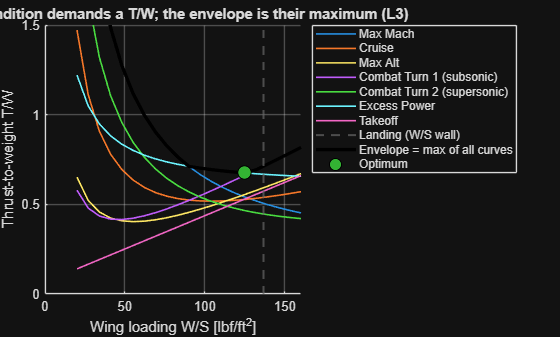

WS = ca.WS_range;
hold on
for i = 1:nC
    c = ca.constraints{i};
    if isa(c, 'Only_WbyS')
        xline(c.WS_max(), '--', 'Color', [0.4 0.4 0.4], 'LineWidth', 1.5, 'DisplayName', c.name + " (W/S wall)");
    else
        plot(WS, c.required_TW(WS), 'LineWidth', 1.2, 'DisplayName', c.name);
    end
end
plot(WS, ca.envelope(), 'k', 'LineWidth', 2.5, 'DisplayName', 'Envelope = max of all curves');
[WS_opt, TW_opt] = ca.optimal_point();
plot(WS_opt, TW_opt, 'o', 'MarkerSize', 10, 'MarkerFaceColor', [0.2 0.7 0.2], 'MarkerEdgeColor', 'k', 'DisplayName', 'Optimum');
hold off
grid on
xlabel('Wing loading W/S [lbf/ft^2]')
ylabel('Thrust-to-weight T/W')
title('Each condition demands a T/W; the envelope is their maximum (L3)')
legend('Location', 'northeastoutside')
ylim([0 1.5])

## The constraint diagram and the optimum

`plot_diagram` draws the finished diagram. It shades the feasible region, draws each curve and wall, and marks the optimum design point.

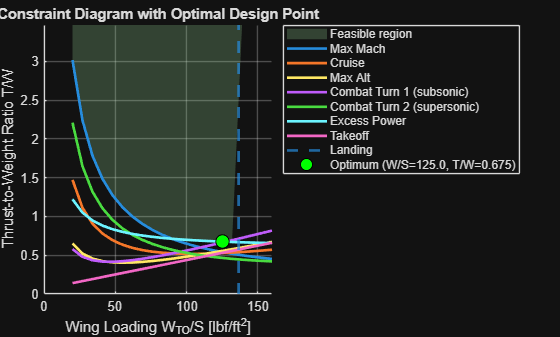

ca.plot_diagram();

`optimal_point` returns the numbers. Compare this optimum with the L1 script. The higher-fidelity drag and lift move the curves, so the optimum shifts.

[WS_opt, TW_opt] = ca.optimal_point();
optimum = table(WS_opt, TW_opt, 'VariableNames', ["WS_opt_lbf_per_ft2", "TW_opt"])

optimum = 1×2 table
    WS_opt_lbf_per_ft2    TW_opt 
    __________________    _______

           125            0.67499


## Summary

The L3 geometry model set the wetted areas and the planform. The L3 aerodynamics model read those live and built the drag polar. The L2 propulsion model set the thrust lapse and the thrust datum. Together they placed the eight conditions on the plane, and the envelope gave the optimum.

The dependency chain, propulsion into geometry into aerodynamics, is what makes this stack respond to a design change. If an optimizer changes the wing area or the engine thrust, the wetted areas, the drag polar, and the constraint curves all update on the next read.

The coupled sizing loop holds this design point fixed while it iterates the weight and the mission. That loop is a separate pass and is not shown in this script.